close all
clear
clc

% 数据的根路径
test_path = '../imgs/test_imgs';
dataset_path = '../imgs/traffic_sign_dataset'; 

% 获取目录列表
files_list = dir(dataset_path);

% 过滤掉'.'和'..'条目，并提取文件夹名称
class_name = {files_list([files_list.isdir] & ~ismember({files_list.name}, {'.', '..'})).name};

classifier = getClassifier(dataset_path, class_name);

============= 创建数据集 ===========
Processing class -- 向右转弯
Processing class -- 掉头
Processing class -- 机动车行驶
Processing class -- 注意儿童
Processing class -- 注意行人
Processing class -- 禁止单车进入
Processing class -- 禁止右转
Processing class -- 禁止左转
Processing class -- 禁止行人进入
Processing class -- 禁止货车进入
Processing class -- 禁止鸣笛
Processing class -- 限速15公里
Processing class -- 限速30公里
Processing class -- 限速40公里
Processing class -- 限速50公里
Processing class -- 限速60公里
Processing class -- 非目标
============ 训练SVM分类器 =========
历时 94.210542 秒。
Done!


Predicting for 00039.jpg


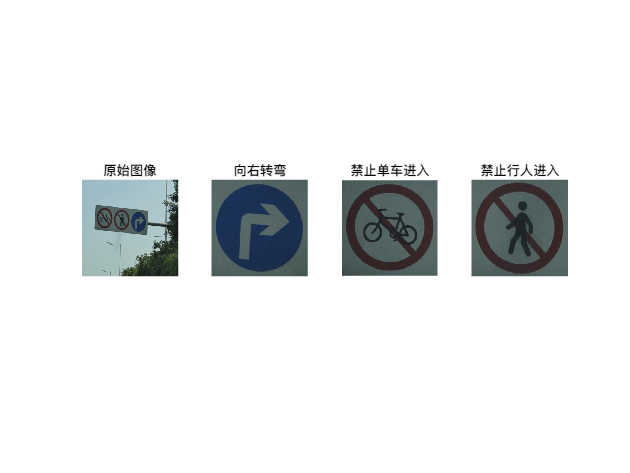

Predicting for 00065.jpg


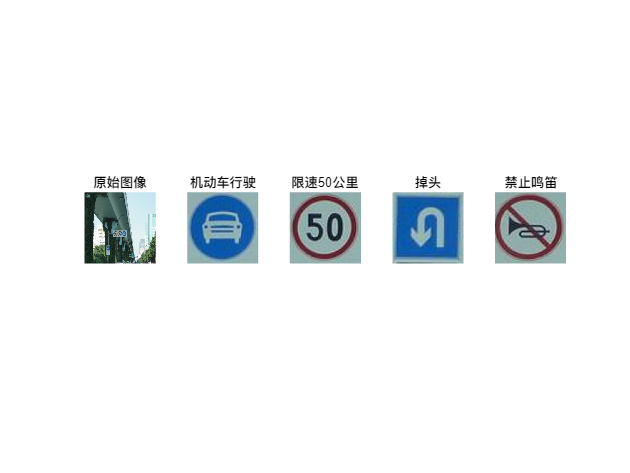

Predicting for 00100.jpg


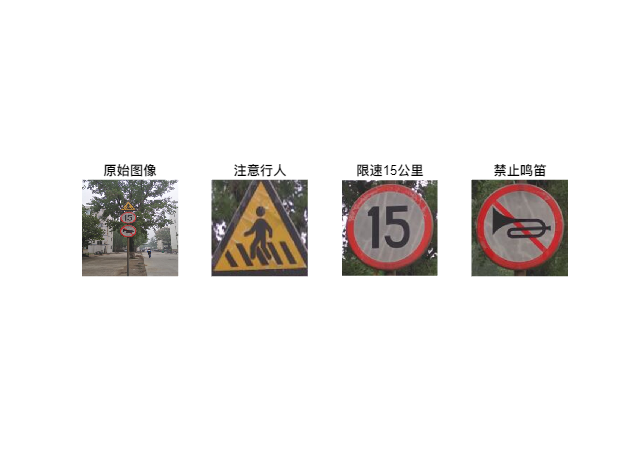

Predicting for 00200.jpg


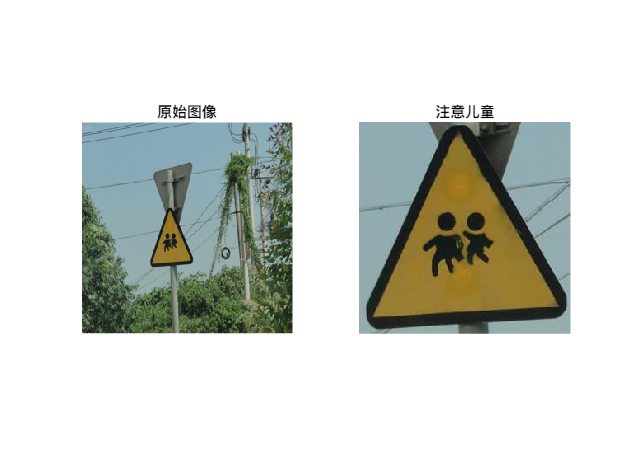

Predicting for 00202.jpg


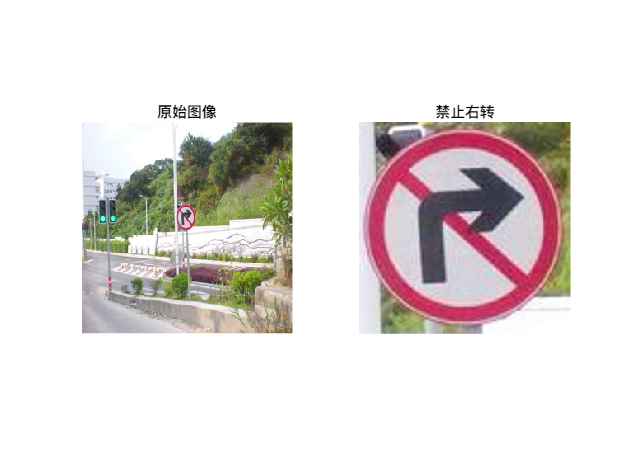

Predicting for 00250.jpg


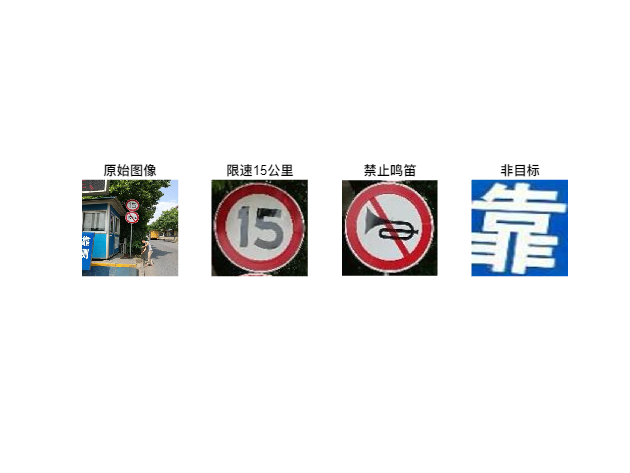

Predicting for 00297.jpg


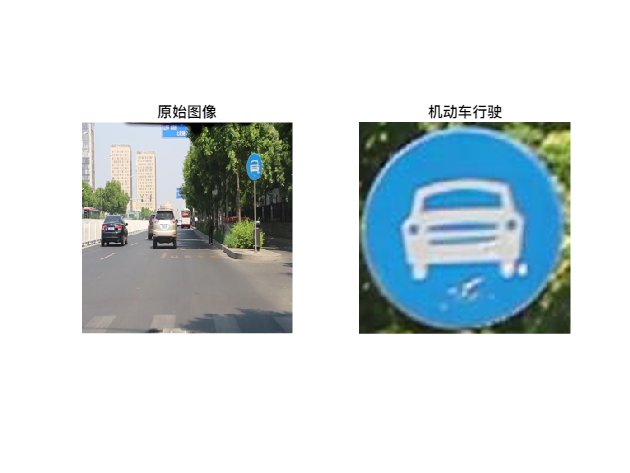

Predicting for 00499.jpg


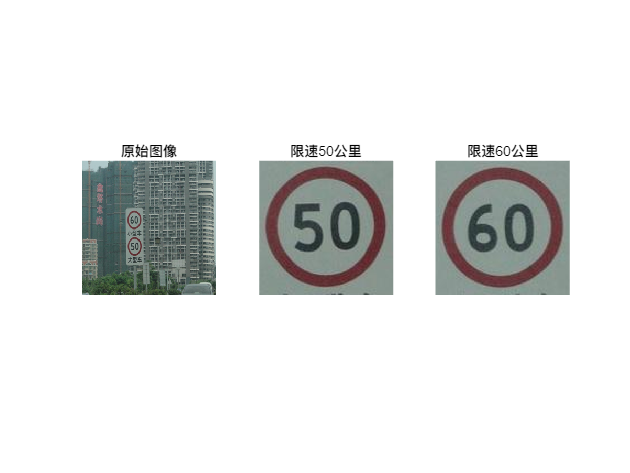

Predicting for 00505.jpg


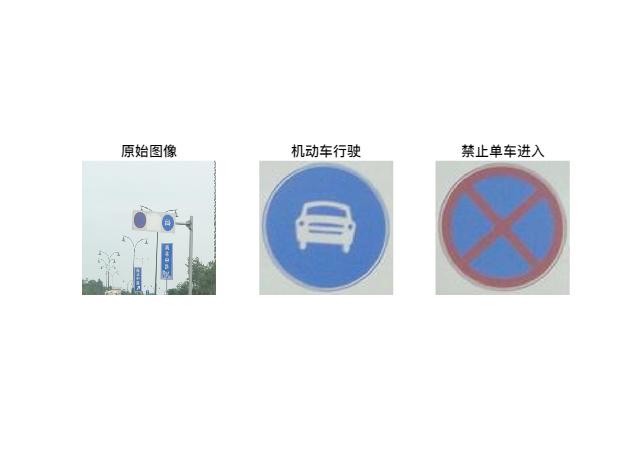

Predicting for 00569.jpg


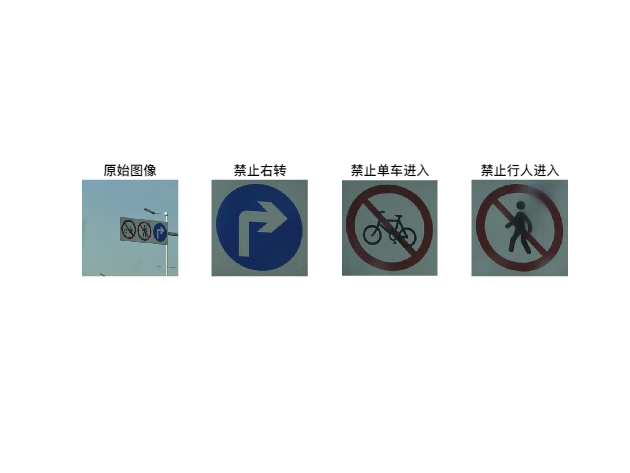

Predicting for 00598.jpg


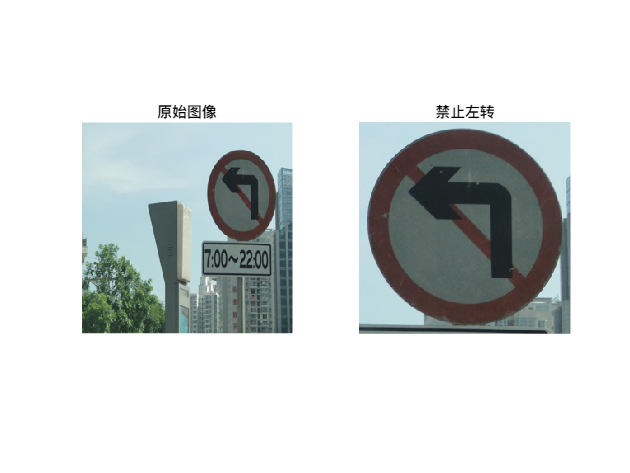

detectRecTrafficSigns(test_path, classifier, class_name)